# **Implementación EC en matlab de modulación digital y analógica**

Andrés Fernando Jerez Medina - 2190416

Jorge Eduardo Angarita Perez - 2190427

Sergio Sebastián Oliveros Sepulveda - 2190396 

## **Punto 2**

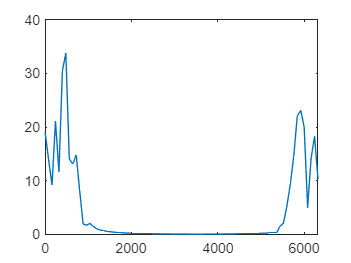

fm = 100;
Ts = 1/(fm*64);
fs = 1/Ts;
fc = fs/8;
Tend = 8*Ts*10;
Ac = 1;
Df = pi/(50.2734);
t = 0:Ts:(Tend-Ts);
n = length(t);
m_t = 10*sin(2*pi*fm*t);
x_t = Ac*cos(Df*int(m_t,Ts));
y_t = Ac*sin(Df*int(m_t,Ts));
g_t = x_t + 1j*y_t;
f = (0:n-1)*(fs/n);
g_f = fft(g_t);
plot(f,abs(g_f))

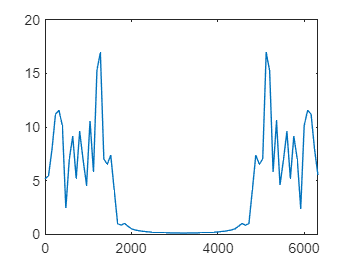

s_t = x_t.*cos(2*pi*fc*t)-y_t.*sin(2*pi*fc*t);
s_f = fft(s_t);
plot(f,abs(s_f))

Funciones usadas

function suma = int(m_t,Ts)
    m = length(m_t);
    suma = zeros(1,m);
    for n = 1:m
        suma(n) = sum(m_t(1:n));
    end
end